# Estudio de conexion entre **componentes gigantes** (**CG**) y Estudio de **cambios de fase**, representación gráfica

Importo

load("MatricesSparse.mat")
max_pais = [1920 3413 6248 8841 9088];%Por si hace falta
autoresF = 1907;% = sum(cont_grados_Colab_F_S)
autoresE = 1489;
autoresA = 2815;
autoresI = 2586;
autoresP = 246;

load("Nodos.mat")
load("Data_CGs.mat")

Cargo las carpetas del directorio al path

addpath(genpath("D:\## DOCUMENTOS ##\UCM\TFG"))

### **NOTACION IMPORTANTE**

Para identificar las matrices y los valores obtenidos en cada conexion se emplea la siguiente nomenclatura

**AF** = Conexion de **Alemania** y **Francia**

**AI** = Conexion de **Alemania** y **Italia**

**AE** = Conexion de **Alemania** y **España**

**AP** = Conexion de **Alemania** y **Portugal**

**FI** = Conexion de **Francia** y **Italia**

**FE** = Conexion de **Francia** y **España** 

**FP** = Conexion de **Francia** y **Portugal**

**IE** = Conexion de **Italia** y **España**

**IP = Conexion de Italia y Portugal**

**EP** = Conexion de **España** y **Portugal**

## Estudio de componentes gigantes de Alemania y Francia (PROCESO DESGLOSADO)

El proceso descrito se incluye dentro de la funcion [analisis_conexion_GC](matlab:open('./analisis_conexion_GC.m'))

% Ale_Fra = blkdiag(adj_GC_A,adj_GC_F);
% figure
% spy(Ale_Fra)
% finAle = size(adj_GC_A,1);
% finFra = size(adj_GC_F,1);

Conecto los 2 **centrales**

% omega = 1;
% Ale_FraCC = Ale_Fra;
% Ale_FraCC(Central_node_A,finAle + Central_node_F) = omega;
% Ale_FraCC(finAle + Central_node_F,Central_node_A) = omega;
% figure
% spy(Ale_FraCC)
% hold on
% plot(Central_node_A,finAle + Central_node_F,'ro')
% plot(finAle + Central_node_F,Central_node_A,'ro')
% hold off %Si no se ven los circulos hacer el plot grande y salen ambos circulos

Calculo la centralidad de esta nueva red

% ec_Ale_FraCC = eigenvector_centrality_und(Ale_FraCC);
% [ec_Ale_FraCC_max, node_ec_Ale_FraCC_max] = max(ec_Ale_FraCC)
% 
% Scaled_ec_Ale_FraCC = ec_Ale_FraCC/max(ec_Ale_FraCC);
% %Mayor autovalor
% [lambda_vec_Ale_FraCC,lambda_Ale_FraCC] = eigs(Ale_FraCC,2);%Cogemos los 2 mas grandes

Calculo la centralidad de la red A, en este caso Alemania

% U_t_1_cc = lambda_vec_Ale_FraCC(:,1);
% C_A_cc = sum(U_t_1_cc(1:finAle))/sum(U_t_1_cc)
% primer_autovalor_CC = lambda_Ale_FraCC(1,1)
% segundo_autovalor_CC = lambda_Ale_FraCC(2,2)

Conecto los 2 **perifericos**

% omega = 1;
% Ale_FraPP = Ale_Fra;
% Ale_FraPP(Peripheral_node_A,finAle + Peripheral_node_F) = omega;
% Ale_FraPP(finAle + Peripheral_node_F,Peripheral_node_A) = omega;
% figure
% spy(Ale_FraPP)
% hold on
% plot(Peripheral_node_A,finAle + Peripheral_node_F,'ro')
% plot(finAle + Peripheral_node_F,Peripheral_node_A,'ro')
% hold off %Si no se ven los circulos hacer el plot grande y salen ambos circulos

Calculo la centralidad de esta nueva red

% ec_Ale_FraPP = eigenvector_centrality_und(Ale_FraPP);
% [ec_Ale_FraPP_max, node_ec_Ale_FraPP_max] = max(ec_Ale_FraPP)
% 
% Scaled_ec_Ale_FraPP = ec_Ale_FraPP/max(ec_Ale_FraPP);
% %Mayor autovalor
% [lambda_vec_Ale_FraPP,lambda_Ale_FraPP] = eigs(Ale_FraPP,2);
% %Cogemos los 2 mas grandes (por si luego queremos algo de ellos)

Calculo la centralidad de la red A, en este caso Alemania

% U_t_1_pp = lambda_vec_Ale_FraPP(:,1);
% C_A_pp = sum(U_t_1_pp(1:finAle))/sum(U_t_1_pp)
% primer_autovalor_PP = lambda_Ale_FraPP(1,1)
% segundo_autovalor_PP = lambda_Ale_FraPP(2,2)

## **Conexion entre CG de Alemania y Francia  AF**

[Mat_AF,Mat_AF_CC,Mat_AF_PP,CA_AF_CC,aut1_AF_CC,aut2_AF_CC,CA_AF_PP,aut1_AF_PP,aut2_AF_PP] = ...
analisis_conexion_GC(adj_GC_A,adj_GC_F,1,Central_node_A,Peripheral_node_A,Central_node_F,Peripheral_node_F);

**Creamos grafica con pesos desde 1 hasta 200**

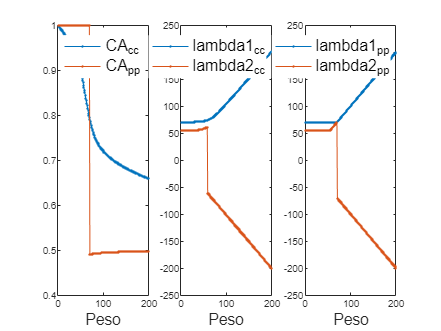

minpeso = 1;
maxpeso = 200;
plotCA_AF_CC = []; plotaut1_AF_CC = []; plotaut2_AF_CC = [];
plotCA_AF_PP = []; plotaut1_AF_PP = []; plotaut2_AF_PP = [];
for i = minpeso:maxpeso
    [Mat_b1_b2,Mat_b1_b2CC,Mat_b1_b2PP,CA_CC,aut1_CC,aut2_CC,CA_PP,aut1_PP,aut2_PP] = ...
    analisis_conexion_GC(adj_GC_A,adj_GC_F,i,Central_node_A,Peripheral_node_A,Central_node_F,Peripheral_node_F);
    plotCA_AF_CC = [plotCA_AF_CC CA_CC];
    plotaut1_AF_CC = [plotaut1_AF_CC aut1_CC];
    plotaut2_AF_CC = [plotaut2_AF_CC aut2_CC];
    plotCA_AF_PP = [plotCA_AF_PP CA_PP];
    plotaut1_AF_PP = [plotaut1_AF_PP aut1_PP];
    plotaut2_AF_PP = [plotaut2_AF_PP aut2_PP];
end

figure
subplot(1,3,1)
plot(minpeso:maxpeso,plotCA_AF_CC,'.-')
hold on
plot(minpeso:maxpeso,plotCA_AF_PP,'.-')
xlabel('Peso','FontSize',13)
legend({'CA_{cc}','CA_{pp}'},...
    'Location','northeast','Box','off','FontSize',13);   
hold off

subplot(1,3,2)
plot(minpeso:maxpeso,plotaut1_AF_CC,'.-')
hold on
plot(minpeso:maxpeso,plotaut2_AF_CC,'.-')
xlabel('Peso','FontSize',13)
legend({'lambda1_{cc}','lambda2_{cc}'},...
    'Location','northeast','Box','off','FontSize',13);   
hold off

subplot(1,3,3)
plot(minpeso:maxpeso,plotaut1_AF_PP,'.-')
hold on
plot(minpeso:maxpeso,plotaut2_AF_PP,'.-')
xlabel('Peso','FontSize',13)
legend({'lambda1_{pp}','lambda2_{pp}'},...
    'Location','northeast','Box','off','FontSize',13);   
hold off

% sgtitle('Alemania-Francia')

## **Conexion entre CG de Alemania y Italia  AI**

[Mat_AI,Mat_AI_CC,Mat_AI_PP,CA_AI_CC,aut1_AI_CC,aut2_AI_CC,CA_AI_PP,aut1_AI_PP,aut2_AI_PP] = ...
analisis_conexion_GC(adj_GC_A,adj_GC_I,1,Central_node_A,Peripheral_node_A,Central_node_I,Peripheral_node_I);

**Creamos grafica con pesos desde 1 hasta 200**

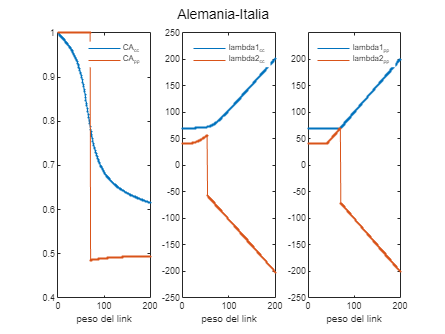

minpeso = 1;
maxpeso = 200;
plotCA_AI_CC = []; plotaut1_AI_CC = []; plotaut2_AI_CC = [];
plotCA_AI_PP = []; plotaut1_AI_PP = []; plotaut2_AI_PP = [];
for i = minpeso:maxpeso
    [Mat_b1_b2,Mat_b1_b2CC,Mat_b1_b2PP,CA_CC,aut1_CC,aut2_CC,CA_PP,aut1_PP,aut2_PP] = ...
    analisis_conexion_GC(adj_GC_A,adj_GC_I,i,Central_node_A,Peripheral_node_A,Central_node_I,Peripheral_node_I);
    plotCA_AI_CC = [plotCA_AI_CC CA_CC];
    plotaut1_AI_CC = [plotaut1_AI_CC aut1_CC];
    plotaut2_AI_CC = [plotaut2_AI_CC aut2_CC];
    plotCA_AI_PP = [plotCA_AI_PP CA_PP];
    plotaut1_AI_PP = [plotaut1_AI_PP aut1_PP];
    plotaut2_AI_PP = [plotaut2_AI_PP aut2_PP];
end

figure
subplot(1,3,1)
plot(minpeso:maxpeso,plotCA_AI_CC,'.-')
hold on
plot(minpeso:maxpeso,plotCA_AI_PP,'.-')
xlabel('peso del link')
legend({'CA_{cc}','CA_{pp}'},...
    'Location','northeast','Box','off','FontSize',13);   
hold off

subplot(1,3,2)
plot(minpeso:maxpeso,plotaut1_AI_CC,'.-')
hold on
plot(minpeso:maxpeso,plotaut2_AI_CC,'.-')
xlabel('peso del link')
legend({'lambda1_{cc}','lambda2_{cc}'},...
    'Location','northeast','Box','off','FontSize',13);   
hold off

subplot(1,3,3)
plot(minpeso:maxpeso,plotaut1_AI_PP,'.-')
hold on
plot(minpeso:maxpeso,plotaut2_AI_PP,'.-')
xlabel('peso del link')
legend({'lambda1_{pp}','lambda2_{pp}'},...
    'Location','northeast','Box','off','FontSize',13);   
hold off
sgtitle('Alemania-Italia')

## **Conexion entre CG de Alemania y España  AE**

[Mat_AE,Mat_AE_CC,Mat_AE_PP,CA_AE_CC,aut1_AE_CC,aut2_AE_CC,CA_AE_PP,aut1_AE_PP,aut2_AE_PP] = ...
analisis_conexion_GC(adj_GC_A,adj_GC_E,1,Central_node_A,Peripheral_node_A,Central_node_E,Peripheral_node_E);

**Creamos grafica con pesos desde 1 hasta 200**

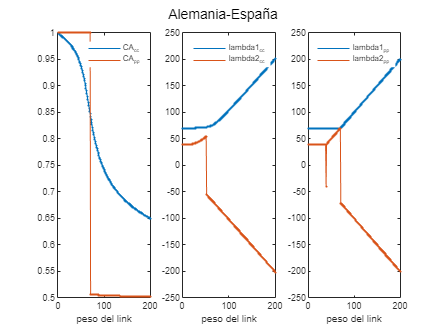

minpeso = 1;
maxpeso = 200;
plotCA_AE_CC = []; plotaut1_AE_CC = []; plotaut2_AE_CC = [];
plotCA_AE_PP = []; plotaut1_AE_PP = []; plotaut2_AE_PP = [];
for i = minpeso:maxpeso
    [Mat_b1_b2,Mat_b1_b2CC,Mat_b1_b2PP,CA_CC,aut1_CC,aut2_CC,CA_PP,aut1_PP,aut2_PP] = ...
    analisis_conexion_GC(adj_GC_A,adj_GC_E,i,Central_node_A,Peripheral_node_A,Central_node_E,Peripheral_node_E);
    plotCA_AE_CC = [plotCA_AE_CC CA_CC];
    plotaut1_AE_CC = [plotaut1_AE_CC aut1_CC];
    plotaut2_AE_CC = [plotaut2_AE_CC aut2_CC];
    plotCA_AE_PP = [plotCA_AE_PP CA_PP];
    plotaut1_AE_PP = [plotaut1_AE_PP aut1_PP];
    plotaut2_AE_PP = [plotaut2_AE_PP aut2_PP];
end

figure
subplot(1,3,1)
plot(minpeso:maxpeso,plotCA_AE_CC,'.-')
hold on
plot(minpeso:maxpeso,plotCA_AE_PP,'.-')
xlabel('peso del link')
legend({'CA_{cc}','CA_{pp}'},...
    'Location','northeast','Box','off');   
hold off

subplot(1,3,2)
plot(minpeso:maxpeso,plotaut1_AE_CC,'.-')
hold on
plot(minpeso:maxpeso,plotaut2_AE_CC,'.-')
xlabel('peso del link')
legend({'lambda1_{cc}','lambda2_{cc}'},...
    'Location','northeast','Box','off');   
hold off

subplot(1,3,3)
plot(minpeso:maxpeso,plotaut1_AE_PP,'.-')
hold on
plot(minpeso:maxpeso,plotaut2_AE_PP,'.-')
xlabel('peso del link')
legend({'lambda1_{pp}','lambda2_{pp}'},...
    'Location','northeast','Box','off');   
hold off
sgtitle('Alemania-España')

## **Conexion entre CG de Alemania y Portugal  AP**

[Mat_AP,Mat_AP_CC,Mat_AP_PP,CA_AP_CC,aut1_AP_CC,aut2_AP_CC,CA_AP_PP,aut1_AP_PP,aut2_AP_PP] = ...
analisis_conexion_GC(adj_GC_A,adj_GC_P,1,Central_node_A,Peripheral_node_A,Central_node_P,Peripheral_node_P);

**Creamos grafica con pesos desde 1 hasta 200**

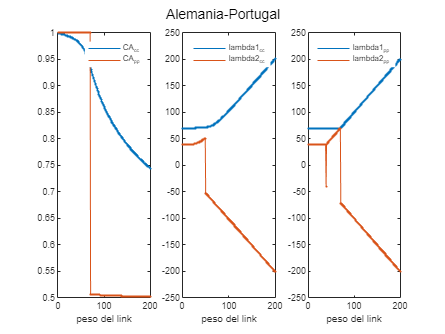

minpeso = 1;
maxpeso = 200;
plotCA_AP_CC = []; plotaut1_AP_CC = []; plotaut2_AP_CC = [];
plotCA_AP_PP = []; plotaut1_AP_PP = []; plotaut2_AP_PP = [];
for i = minpeso:maxpeso
    [Mat_b1_b2,Mat_b1_b2CC,Mat_b1_b2PP,CA_CC,aut1_CC,aut2_CC,CA_PP,aut1_PP,aut2_PP] = ...
    analisis_conexion_GC(adj_GC_A,adj_GC_P,i,Central_node_A,Peripheral_node_A,Central_node_P,Peripheral_node_P);
    plotCA_AP_CC = [plotCA_AP_CC CA_CC];
    plotaut1_AP_CC = [plotaut1_AP_CC aut1_CC];
    plotaut2_AP_CC = [plotaut2_AP_CC aut2_CC];
    plotCA_AP_PP = [plotCA_AP_PP CA_PP];
    plotaut1_AP_PP = [plotaut1_AP_PP aut1_PP];
    plotaut2_AP_PP = [plotaut2_AP_PP aut2_PP];
end

figure
subplot(1,3,1)
plot(minpeso:maxpeso,plotCA_AP_CC,'.-')
hold on
plot(minpeso:maxpeso,plotCA_AP_PP,'.-')
xlabel('peso del link')
legend({'CA_{cc}','CA_{pp}'},...
    'Location','northeast','Box','off');   
hold off

subplot(1,3,2)
plot(minpeso:maxpeso,plotaut1_AP_CC,'.-')
hold on
plot(minpeso:maxpeso,plotaut2_AP_CC,'.-')
xlabel('peso del link')
legend({'lambda1_{cc}','lambda2_{cc}'},...
    'Location','northeast','Box','off');   
hold off

subplot(1,3,3)
plot(minpeso:maxpeso,plotaut1_AP_PP,'.-')
hold on
plot(minpeso:maxpeso,plotaut2_AP_PP,'.-')
xlabel('peso del link')
legend({'lambda1_{pp}','lambda2_{pp}'},...
    'Location','northeast','Box','off');   
hold off
sgtitle('Alemania-Portugal')

## **Conexion entre CG de Francia y Italia  FI**

[Mat_FI,Mat_FI_CC,Mat_FI_PP,CA_FI_CC,aut1_FI_CC,aut2_FI_CC,CA_FI_PP,aut1_FI_PP,aut2_FI_PP] = ...
analisis_conexion_GC(adj_GC_F,adj_GC_I,1,Central_node_F,Peripheral_node_F,Central_node_I,Peripheral_node_I);

**Creamos grafica con pesos desde 1 hasta 200**

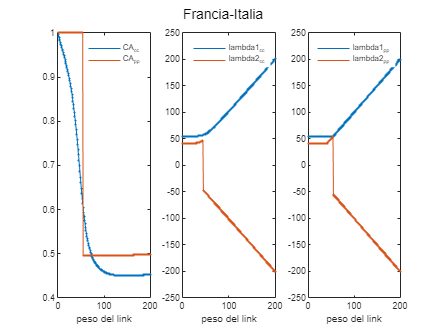

minpeso = 1;
maxpeso = 200;
plotCA_FI_CC = []; plotaut1_FI_CC = []; plotaut2_FI_CC = [];
plotCA_FI_PP = []; plotaut1_FI_PP = []; plotaut2_FI_PP = [];
for i = minpeso:maxpeso
    [Mat_b1_b2,Mat_b1_b2CC,Mat_b1_b2PP,CA_CC,aut1_CC,aut2_CC,CA_PP,aut1_PP,aut2_PP] = ...
    analisis_conexion_GC(adj_GC_F,adj_GC_I,i,Central_node_F,Peripheral_node_F,Central_node_I,Peripheral_node_I);
    plotCA_FI_CC = [plotCA_FI_CC CA_CC];
    plotaut1_FI_CC = [plotaut1_FI_CC aut1_CC];
    plotaut2_FI_CC = [plotaut2_FI_CC aut2_CC];
    plotCA_FI_PP = [plotCA_FI_PP CA_PP];
    plotaut1_FI_PP = [plotaut1_FI_PP aut1_PP];
    plotaut2_FI_PP = [plotaut2_FI_PP aut2_PP];
end

figure
subplot(1,3,1)
plot(minpeso:maxpeso,plotCA_FI_CC,'.-')
hold on
plot(minpeso:maxpeso,plotCA_FI_PP,'.-')
xlabel('peso del link')
legend({'CA_{cc}','CA_{pp}'},...
    'Location','northeast','Box','off');   
hold off

subplot(1,3,2)
plot(minpeso:maxpeso,plotaut1_FI_CC,'.-')
hold on
plot(minpeso:maxpeso,plotaut2_FI_CC,'.-')
xlabel('peso del link')
legend({'lambda1_{cc}','lambda2_{cc}'},...
    'Location','northeast','Box','off');   
hold off

subplot(1,3,3)
plot(minpeso:maxpeso,plotaut1_FI_PP,'.-')
hold on
plot(minpeso:maxpeso,plotaut2_FI_PP,'.-')
xlabel('peso del link')
legend({'lambda1_{pp}','lambda2_{pp}'},...
    'Location','northeast','Box','off');   
hold off
sgtitle('Francia-Italia')

## **Conexion entre CG de Francia y España  FE**

[Mat_FE,Mat_FE_CC,Mat_FE_PP,CA_FE_CC,aut1_FE_CC,aut2_FE_CC,CA_FE_PP,aut1_FE_PP,aut2_FE_PP] = ...
analisis_conexion_GC(adj_GC_F,adj_GC_E,1,Central_node_F,Peripheral_node_F,Central_node_E,Peripheral_node_E);

**Creamos grafica con pesos desde 1 hasta 200**

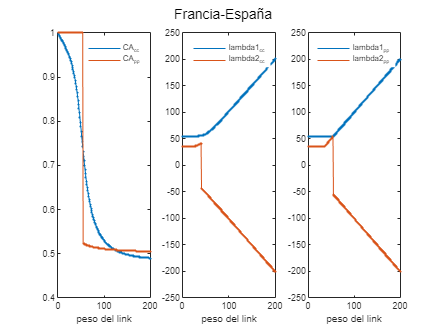

minpeso = 1;
maxpeso = 200;
plotCA_FE_CC = []; plotaut1_FE_CC = []; plotaut2_FE_CC = [];
plotCA_FE_PP = []; plotaut1_FE_PP = []; plotaut2_FE_PP = [];
for i = minpeso:maxpeso
    [Mat_b1_b2,Mat_b1_b2CC,Mat_b1_b2PP,CA_CC,aut1_CC,aut2_CC,CA_PP,aut1_PP,aut2_PP] = ...
    analisis_conexion_GC(adj_GC_F,adj_GC_E,i,Central_node_F,Peripheral_node_F,Central_node_E,Peripheral_node_E);
    plotCA_FE_CC = [plotCA_FE_CC CA_CC];
    plotaut1_FE_CC = [plotaut1_FE_CC aut1_CC];
    plotaut2_FE_CC = [plotaut2_FE_CC aut2_CC];
    plotCA_FE_PP = [plotCA_FE_PP CA_PP];
    plotaut1_FE_PP = [plotaut1_FE_PP aut1_PP];
    plotaut2_FE_PP = [plotaut2_FE_PP aut2_PP];
end


figure
subplot(1,3,1)
plot(minpeso:maxpeso,plotCA_FE_CC,'.-')
hold on
plot(minpeso:maxpeso,plotCA_FE_PP,'.-')
xlabel('peso del link')
legend({'CA_{cc}','CA_{pp}'},...
    'Location','northeast','Box','off');   
hold off

subplot(1,3,2)
plot(minpeso:maxpeso,plotaut1_FE_CC,'.-')
hold on
plot(minpeso:maxpeso,plotaut2_FE_CC,'.-')
xlabel('peso del link')
legend({'lambda1_{cc}','lambda2_{cc}'},...
    'Location','northeast','Box','off');   
hold off

subplot(1,3,3)
plot(minpeso:maxpeso,plotaut1_FE_PP,'.-')
hold on
plot(minpeso:maxpeso,plotaut2_FE_PP,'.-')
xlabel('peso del link')
legend({'lambda1_{pp}','lambda2_{pp}'},...
    'Location','northeast','Box','off');   
hold off
sgtitle('Francia-España')

## **Conexion entre CG de Francia y Portugal  FP**

[Mat_FP,Mat_FP_CC,Mat_FP_PP,CA_FP_CC,aut1_FP_CC,aut2_FP_CC,CA_FP_PP,aut1_FP_PP,aut2_FP_PP] = ...
analisis_conexion_GC(adj_GC_F,adj_GC_P,1,Central_node_F,Peripheral_node_F,Central_node_P ,Peripheral_node_P);

**Creamos grafica con pesos desde 1 hasta 200**

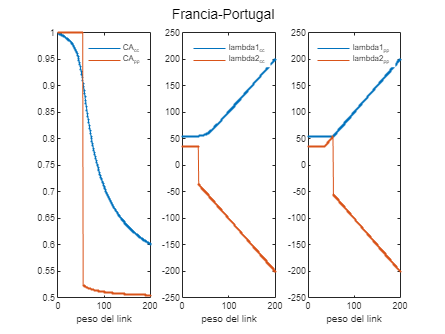

minpeso = 1;
maxpeso = 200;
plotCA_FP_CC = []; plotaut1_FP_CC = []; plotaut2_FP_CC = [];
plotCA_FP_PP = []; plotaut1_FP_PP = []; plotaut2_FP_PP = [];
for i = minpeso:maxpeso
    [Mat_b1_b2,Mat_b1_b2CC,Mat_b1_b2PP,CA_CC,aut1_CC,aut2_CC,CA_PP,aut1_PP,aut2_PP] = ...
    analisis_conexion_GC(adj_GC_F,adj_GC_P,i,Central_node_F,Peripheral_node_F,Central_node_P,Peripheral_node_P);
    plotCA_FP_CC = [plotCA_FP_CC CA_CC];
    plotaut1_FP_CC = [plotaut1_FP_CC aut1_CC];
    plotaut2_FP_CC = [plotaut2_FP_CC aut2_CC];
    plotCA_FP_PP = [plotCA_FP_PP CA_PP];
    plotaut1_FP_PP = [plotaut1_FP_PP aut1_PP];
    plotaut2_FP_PP = [plotaut2_FP_PP aut2_PP];
end



figure
subplot(1,3,1)
plot(minpeso:maxpeso,plotCA_FP_CC,'.-')
hold on
plot(minpeso:maxpeso,plotCA_FP_PP,'.-')
xlabel('peso del link')
legend({'CA_{cc}','CA_{pp}'},...
    'Location','northeast','Box','off');   
hold off

subplot(1,3,2)
plot(minpeso:maxpeso,plotaut1_FP_CC,'.-')
hold on
plot(minpeso:maxpeso,plotaut2_FP_CC,'.-')
xlabel('peso del link')
legend({'lambda1_{cc}','lambda2_{cc}'},...
    'Location','northeast','Box','off');   
hold off

subplot(1,3,3)
plot(minpeso:maxpeso,plotaut1_FP_PP,'.-')
hold on
plot(minpeso:maxpeso,plotaut2_FP_PP,'.-')
xlabel('peso del link')
legend({'lambda1_{pp}','lambda2_{pp}'},...
    'Location','northeast','Box','off');   
hold off
sgtitle('Francia-Portugal')

## **Conexion entre CG de Italia y España  IE**

[Mat_IE,Mat_IE_CC,Mat_IE_PP,CA_IE_CC,aut1_IE_CC,aut2_IE_CC,CA_IE_PP,aut1_IE_PP,aut2_IE_PP] = ...
analisis_conexion_GC(adj_GC_I,adj_GC_E,1,Central_node_I,Peripheral_node_I,Central_node_E,Peripheral_node_E);

**Creamos grafica con pesos desde 1 hasta 200**

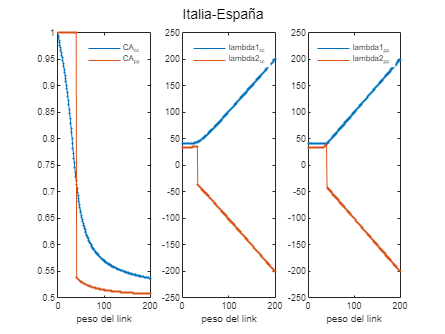

minpeso = 1;
maxpeso = 200;
plotCA_IE_CC = []; plotaut1_IE_CC = []; plotaut2_IE_CC = [];
plotCA_IE_PP = []; plotaut1_IE_PP = []; plotaut2_IE_PP = [];
for i = minpeso:maxpeso
    [Mat_b1_b2,Mat_b1_b2CC,Mat_b1_b2PP,CA_CC,aut1_CC,aut2_CC,CA_PP,aut1_PP,aut2_PP] = ...
    analisis_conexion_GC(adj_GC_I,adj_GC_E,i,Central_node_I,Peripheral_node_I,Central_node_E,Peripheral_node_E);
    plotCA_IE_CC = [plotCA_IE_CC CA_CC];
    plotaut1_IE_CC = [plotaut1_IE_CC aut1_CC];
    plotaut2_IE_CC = [plotaut2_IE_CC aut2_CC];
    plotCA_IE_PP = [plotCA_IE_PP CA_PP];
    plotaut1_IE_PP = [plotaut1_IE_PP aut1_PP];
    plotaut2_IE_PP = [plotaut2_IE_PP aut2_PP];
end



figure
subplot(1,3,1)
plot(minpeso:maxpeso,plotCA_IE_CC,'.-')
hold on
plot(minpeso:maxpeso,plotCA_IE_PP,'.-')
xlabel('peso del link')
legend({'CA_{cc}','CA_{pp}'},...
    'Location','northeast','Box','off');   
hold off

subplot(1,3,2)
plot(minpeso:maxpeso,plotaut1_IE_CC,'.-')
hold on
plot(minpeso:maxpeso,plotaut2_IE_CC,'.-')
xlabel('peso del link')
legend({'lambda1_{cc}','lambda2_{cc}'},...
    'Location','northeast','Box','off');   
hold off

subplot(1,3,3)
plot(minpeso:maxpeso,plotaut1_IE_PP,'.-')
hold on
plot(minpeso:maxpeso,plotaut2_IE_PP,'.-')
xlabel('peso del link')
legend({'lambda1_{pp}','lambda2_{pp}'},...
    'Location','northeast','Box','off');   
hold off
sgtitle('Italia-España')

## **Conexion entre CG de Italia y Portugal  IP**

[Mat_IP,Mat_IP_CC,Mat_IP_PP,CA_IP_CC,aut1_IP_CC,aut2_IP_CC,CA_IP_PP,aut1_IP_PP,aut2_IP_PP] = ...
analisis_conexion_GC(adj_GC_I,adj_GC_P,1,Central_node_I,Peripheral_node_I,Central_node_P,Peripheral_node_P);

**Creamos grafica con pesos desde 1 hasta 200**

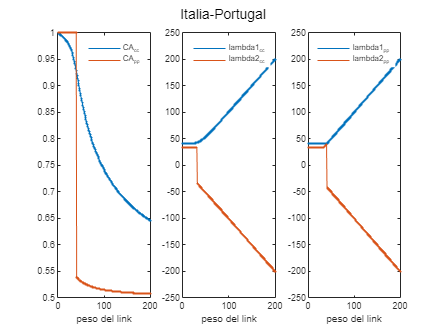

minpeso = 1;
maxpeso = 200;
plotCA_IP_CC = []; plotaut1_IP_CC = []; plotaut2_IP_CC = [];
plotCA_IP_PP = []; plotaut1_IP_PP = []; plotaut2_IP_PP = [];
for i = minpeso:maxpeso
    [Mat_b1_b2,Mat_b1_b2CC,Mat_b1_b2PP,CA_CC,aut1_CC,aut2_CC,CA_PP,aut1_PP,aut2_PP] = ...
    analisis_conexion_GC(adj_GC_I,adj_GC_P,i,Central_node_I,Peripheral_node_I,Central_node_P,Peripheral_node_P);
    plotCA_IP_CC = [plotCA_IP_CC CA_CC];
    plotaut1_IP_CC = [plotaut1_IP_CC aut1_CC];
    plotaut2_IP_CC = [plotaut2_IP_CC aut2_CC];
    plotCA_IP_PP = [plotCA_IP_PP CA_PP];
    plotaut1_IP_PP = [plotaut1_IP_PP aut1_PP];
    plotaut2_IP_PP = [plotaut2_IP_PP aut2_PP];
end


figure
subplot(1,3,1)
plot(minpeso:maxpeso,plotCA_IP_CC,'.-')
hold on
plot(minpeso:maxpeso,plotCA_IP_PP,'.-')
xlabel('peso del link')
legend({'CA_{cc}','CA_{pp}'},...
    'Location','northeast','Box','off');   
hold off

subplot(1,3,2)
plot(minpeso:maxpeso,plotaut1_IP_CC,'.-')
hold on
plot(minpeso:maxpeso,plotaut2_IP_CC,'.-')
xlabel('peso del link')
legend({'lambda1_{cc}','lambda2_{cc}'},...
    'Location','northeast','Box','off');   
hold off

subplot(1,3,3)
plot(minpeso:maxpeso,plotaut1_IP_PP,'.-')
hold on
plot(minpeso:maxpeso,plotaut2_IP_PP,'.-')
xlabel('peso del link')
legend({'lambda1_{pp}','lambda2_{pp}'},...
    'Location','northeast','Box','off');   
hold off
sgtitle('Italia-Portugal')

## **Conexion entre CG de España y Portugal  EP**

[Mat_EP,Mat_EP_CC,Mat_EP_PP,CA_EP_CC,aut1_EP_CC,aut2_EP_CC,CA_EP_PP,aut1_EP_PP,aut2_EP_PP] = ...
analisis_conexion_GC(adj_GC_E,adj_GC_P,1,Central_node_E,Peripheral_node_E,Central_node_P,Peripheral_node_P);

**Creamos grafica con pesos desde 1 hasta 200**

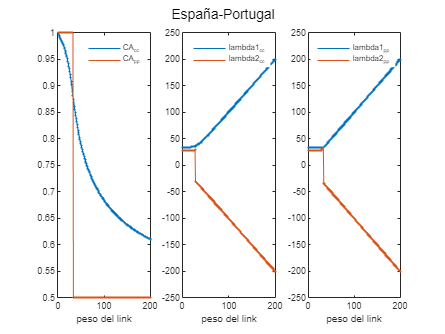

minpeso = 1;
maxpeso = 200;
plotCA_EP_CC = []; plotaut1_EP_CC = []; plotaut2_EP_CC = [];
plotCA_EP_PP = []; plotaut1_EP_PP = []; plotaut2_EP_PP = [];
for i = minpeso:maxpeso
    [Mat_b1_b2,Mat_b1_b2CC,Mat_b1_b2PP,CA_CC,aut1_CC,aut2_CC,CA_PP,aut1_PP,aut2_PP] = ...
    analisis_conexion_GC(adj_GC_E,adj_GC_P,i,Central_node_E,Peripheral_node_E,Central_node_P,Peripheral_node_P);
    plotCA_EP_CC = [plotCA_EP_CC CA_CC];
    plotaut1_EP_CC = [plotaut1_EP_CC aut1_CC];
    plotaut2_EP_CC = [plotaut2_EP_CC aut2_CC];
    plotCA_EP_PP = [plotCA_EP_PP CA_PP];
    plotaut1_EP_PP = [plotaut1_EP_PP aut1_PP];
    plotaut2_EP_PP = [plotaut2_EP_PP aut2_PP];
end


figure
subplot(1,3,1)
plot(minpeso:maxpeso,plotCA_EP_CC,'.-')
hold on
plot(minpeso:maxpeso,plotCA_EP_PP,'.-')
xlabel('peso del link')
legend({'CA_{cc}','CA_{pp}'},...
    'Location','northeast','Box','off');   
hold off

subplot(1,3,2)
plot(minpeso:maxpeso,plotaut1_EP_CC,'.-')
hold on
plot(minpeso:maxpeso,plotaut2_EP_CC,'.-')
xlabel('peso del link')
legend({'lambda1_{cc}','lambda2_{cc}'},...
    'Location','northeast','Box','off');   
hold off

subplot(1,3,3)
plot(minpeso:maxpeso,plotaut1_EP_PP,'.-')
hold on
plot(minpeso:maxpeso,plotaut2_EP_PP,'.-')
xlabel('peso del link')
legend({'lambda1_{pp}','lambda2_{pp}'},...
    'Location','northeast','Box','off');   
hold off
sgtitle('España-Portugal')

Guardamos variables primero en un fichero parcial y luego en uno completo

save("Analisis_GC.mat",...
    "plotCA_AF_CC","plotCA_AF_PP","plotaut1_AF_CC","plotaut2_AF_CC","plotaut1_AF_PP","plotaut2_AF_PP",...
    "plotCA_AI_CC","plotCA_AI_PP","plotaut1_AI_CC","plotaut2_AI_CC","plotaut1_AI_PP","plotaut2_AI_PP",...
    "plotCA_AE_CC","plotCA_AE_PP","plotaut1_AE_CC","plotaut2_AE_CC","plotaut1_AE_PP","plotaut2_AE_PP",...
    "plotCA_AP_CC","plotCA_AP_PP","plotaut1_AP_CC","plotaut2_AP_CC","plotaut1_AP_PP","plotaut2_AP_PP",...
    "plotCA_FI_CC","plotCA_FI_PP","plotaut1_FI_CC","plotaut2_FI_CC","plotaut1_FI_PP","plotaut2_FI_PP",...
    "plotCA_FE_CC","plotCA_FE_PP","plotaut1_FE_CC","plotaut2_FE_CC","plotaut1_FE_PP","plotaut2_FE_PP",...
    "plotCA_FP_CC","plotCA_FP_PP","plotaut1_FP_CC","plotaut2_FP_CC","plotaut1_FP_PP","plotaut2_FP_PP",...
    "plotCA_IE_CC","plotCA_IE_PP","plotaut1_IE_CC","plotaut2_IE_CC","plotaut1_IE_PP","plotaut2_IE_PP",...
    "plotCA_IP_CC","plotCA_IP_PP","plotaut1_IP_CC","plotaut2_IP_CC","plotaut1_IP_PP","plotaut2_IP_PP",...
    "plotCA_EP_CC","plotCA_EP_PP","plotaut1_EP_CC","plotaut2_EP_CC","plotaut1_EP_PP","plotaut2_EP_PP");

Guardamos TODAS las variables de este doc

save("Var_Archivo_3_TFG.mat")